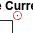

exp1 = readtable('lab3-exp1.csv');
exp1.current_collector = abs(exp1.Var3) - abs(exp1.Var2);

exp1 = exp1(exp1.Var1 < 0.775, :);
exp1 = exp1(exp1.Var1 > 0.5, :);

v_exp1 = flipud(exp1.Var1);
i_c_exp1 = flipud(exp1.current_collector);
i_b_exp1 = flipud(exp1.Var2);

% Plotting , v_exp1, i_b_exp1, 'ro'
semilogy(v_exp1, i_c_exp1, 'bo' , v_exp1, i_b_exp1, 'ro');
xlabel('Base Voltage (V)');
ylabel('Current (A)');
title('Collector and Base Current vs Base Voltage');
grid on;

% Theoretical fit for collector current (example)
% Assuming a linear relationship for simplicity
fit_i_c = polyfit(v_exp1, log(i_c_exp1), 1);
i_c_fit = exp(polyval(fit_i_c, v_exp1));

% Plotting the theoretical fit for collector current
hold on;
plot(v_exp1, i_c_fit, 'r--');

% Theoretical fit for base current (example)
% Assuming a power-law relationship for simplicity
fit_i_b = polyfit(v_exp1, log(i_b_exp1), 1);
i_b_fit = exp(polyval(fit_i_b, v_exp1));

% Plotting the theoretical fit for base current
plot(v_exp1, i_b_fit, 'b--');
legend('Collector Current', 'Base Current', 'Theoretical fit Collector Current', 'Theoretical fit Base Current');

% Display parameter values
fprintf('Collector Current Fit: y = %.4f * x + %.4f\n', fit_i_c(1), fit_i_c(2));

Collector Current Fit: y = 37.5455 * x + -32.0614


disp(fit_i_b);

   38.3947  -37.8107

